# Dose kernel and diffusion voxel creation

## Load dose data

%clear all
load 05nmPd20nmFeO_combined.data
Dose_full = X05nmPd20nmFeO_combined

Dose_full = 1.0e+11 *

    0.0000    4.9365
    0.0000    0.2147
    0.0000    0.2016
    0.0000    0.2020
    0.0000    0.1942
    0.0000    0.1865
    0.0000    0.1919
    0.0000    0.1924
    0.0000    0.1819
    0.0000    0.1776


Dose_full2 = X05nmPd20nmFeO_combined

Dose_full2 = 1.0e+11 *

    0.0000    4.9365
    0.0000    0.2147
    0.0000    0.2016
    0.0000    0.2020
    0.0000    0.1942
    0.0000    0.1865
    0.0000    0.1919
    0.0000    0.1924
    0.0000    0.1819
    0.0000    0.1776


Dose_part = Dose_full(1:100,1)

Dose_part = 1.0e-04 *

    0.0203
    0.0207
    0.0210
    0.0214
    0.0218
    0.0222
    0.0226
    0.0230
    0.0234
    0.0238


## Remove data of distances not interesting for calculations

R_NP = Dose_full(:,1) % distance from centre nanoparticle in mm

R_NP =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


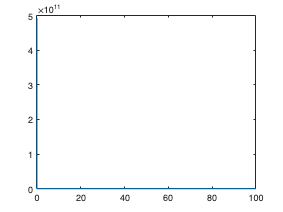

figure 
plot(Dose_full(:,1),Dose_full(:,2))


Dose_full(any(R_NP>=0.5,2),:) = [];       % remove all rows of Dose where the distance from the centre of NP is larger than 0.5 mm
%Dose_full(any(R_NP<=0.1,2),:) = [];       % remove all rows of Dose where the distance from the centre of NP is smaller than 0.1 mm
Dose_full(1,2)

ans = 4.9365e+11

Dose_firstpart = zeros(length(Dose_full),1);
Dose_firstpart(1,1) = Dose_full(1,2)*(Dose_full(1,1)-0);
for i = 2:length(Dose_full)
    Dose_firstpart(i,1) = Dose_full(i,2)*(Dose_full(i,1)-Dose_full(i-1,1)); % Integral over first part of dose distribution
%    Dose_firstpart(i,1) = Dose_full(i,1);
end
Additional_dose = sum(Dose_firstpart)

Additional_dose = 1.0310e+06


Dose_full2(any(R_NP<=0.5,2),:) = [];       % remove all rows of Dose where the distance from the centre of NP is larger than 0.5 mm

Dose_full2(1,2) = Dose_full2(1,2) + Additional_dose;
%Dose_average_begin = mean(Dose_firstpart)
%Dose_minsmall(any(R_NP>=0.5,2),:) = []

% Dose_full2(1:10,2)
Dose_end = Dose_full2;

Dose(:,1) = Dose_end(:,1)/10;            % convert distance from centre NP from mm to cm (<- order in model)

Dose(1,2) = Dose_end(1,2).* 1.*((70*10^6./(7.97*10^9)) ./ (4/3*pi.* (Dose_end(1,1).^3)  *10^5./3600));
for i = 2:length(Dose_end(:,2))
    Dose(i,2) = Dose_end(i,2).* 1.*((70*10^6./(7.97*10^9)) ./ (4/3*pi.* (Dose_end(i,1).^3 - Dose_end(i-1,1).^3 )  *10^5./3600));%  ((10^5*pi.*Dose_end(:,1) ./3600)));% 1 * activity my model / activity Rogier % compensated using the difference in activity between dose distribution and activity of my model
end
Dose_1 = Dose(2:end,2)

Dose_1 = 1.0e-07 *

    0.5453
    0.3972
    0.4623
    0.4825
    0.3653
    0.3366
    0.2984
    0.2772
    0.2814
    0.2293


%figure;
%semilogx(Dose1(:,1),Dose1(:,2));

% finer_dose_distri = 0.1:0.05:10
% Dose_interpolated1 = interp1(Dose(:,1),Dose(:,2),finer_dose_distri')
% Dose_interpolated1D = [finer_dose_distri' Dose_interpolated1]
% 
% semilogx(Dose_interpolated1D(:,1),Dose_interpolated1D(:,2))
% 

%% create symmetrical radial dose distribution:
Dose_neg(:,1) = -Dose(:,1);
Dose_neg(:,2) = Dose(:,2);
Dose_neg = sort(Dose_neg);
Dose_distance = zeros(2*length(Dose(:,1))-1,2);
Dose_distance(1:end/2+1,:) = Dose_neg;

Dose_distance(end/2:end,:) = Dose

Dose_distance =   -10.0000    0.0000
   -9.8241    0.0000
   -9.6513    0.0000
   -9.4815    0.0000
   -9.3147    0.0000
   -9.1509    0.0000
   -8.9899    0.0000
   -8.8317    0.0000
   -8.6764    0.0000
   -8.5237    0.0000


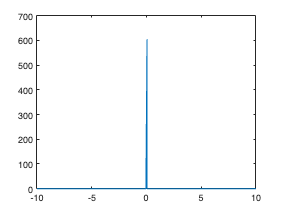


plot(Dose_distance(:,1),Dose_distance(:,2))

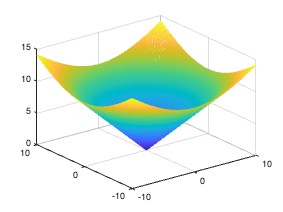


[XDose,YDose] = meshgrid(Dose_distance(:,1),Dose_distance(:,1));
XDose_array = reshape(XDose,[],1);
YDose_array = reshape(YDose,[],1);

Distance_eachpoint = zeros(length(Dose_distance(:,2)),length(Dose_distance(:,2)));
Dose_eachpoint = zeros(length(Dose_distance(:,2)),length(Dose_distance(:,2)));
for i = 1:length(Dose_distance(:,1))
    for j = 1:length(Dose_distance(:,1))
            Distance_eachpoint(i,j) = sqrt(XDose(i,j).^2+YDose(i,j).^2);
% dose_distanceX = abs(X_conc(j) - Xmesh(i)); % check absolute distance between centre node j and X coordinate i
% dose_distanceY = abs(Y_conc(j) - Ymesh(i)); % Check absolute distance between centre node j and Y coordinate i
%Distance_from_centre = sqrt(dose_distanceX^2+dose_distanceY^2); % find Pythagoras c size to know distance between centre j and point i
            if Distance_eachpoint(i,j) < 10
                [minvalue,closestIndex] = min(abs(Dose(:,1) - Distance_eachpoint(i,j)));
                Dose_eachpoint(i,j) = Dose(closestIndex,2); % find corresponding dose to dose element and assign to meshnode element i 
            else
                Dose_eachpoint(i,j) = 0;        % for distances larger than 10 cm, no dose is deposited
            end   
    end 
end
mesh(Dose_distance(:,1),Dose_distance(:,1),Distance_eachpoint)


Dose_eachpoint

Dose_eachpoint = 1.0e-08 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

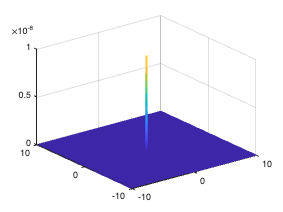


figure
mesh(Dose_distance(:,1), Dose_distance(:,1),Dose_eachpoint)

%set(gca, 'ZScale', 'log')
%zlim([10^(-25) 10^(-1)])

## Create kernel of dose

Dose_array = reshape(Dose_eachpoint,[],1);

Dose_voxel = scatteredInterpolant(XDose_array,YDose_array,Dose_array)

Dose_voxel =   scatteredInterpolant with properties:

                 Points: [356409×2 double]
                 Values: [356409×1 double]
                 Method: 'linear'
    ExtrapolationMethod: 'linear'


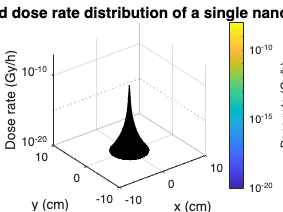


[xq,yq] = ndgrid(-10:0.1:10);
Dose_kernel = Dose_voxel(xq,yq)*0.05*0.05;

figure
surf(xq,yq,Dose_kernel)
set(gca, 'ZScale', 'log')
zlim([10^(-20) 10^(-7)])
set(gca, 'ColorScale', 'log','FontSize',13)
caxis([10^(-20) 10^(-8)])
xlabel('x (cm)','FontSize',15)
ylabel('y (cm)','FontSize',15)
zlabel('Dose rate (Gy/h)','FontSize',15)
title('2D voxelized dose rate distribution of a single nanoparticle','FontSize',17)
clb = colorbar;
set(get(clb,'label'),'string','Dose rate (Gy/h)','FontSize',13);



sum(Dose(:,2))

ans = 605.0812

Dose_max = sum(sum(Dose_kernel))

Dose_max = 4.0551e-11

# Concentration transformation and dose calculation

## Change conc. data to voxel mesh

Cresults_XZ_default = load('Cresults_XZ_default.mat');

Cresults_YZ_default = load('Cresults_YZ_default.mat');

Cresults_D0 = load('Cresults_D0.mat');


Cresults_ci_min = load('Cresults_ci_min.mat');

Error using load
Unable to find file or directory 'Cresults_ci_min.mat'.

Cresults_ci_max = load('Cresults_ci_max.mat');


Cresults_D_min = load('Cresults_D_min.mat');

Cresults_D_max = load('Cresults_D_max.mat');






Cresults_YZ_default.Cresults = Cresults_YZ_default.Cresults .*10^3;
x1 = Cresults_YZ_default.Xnodes;
y1 = Cresults_YZ_default.Ynodes;

%[xq,yq] = ndgrid(0:0.05:8); % voxel size of 0.02 cm --> 0.2 mm

% F2 = scatteredInterpolant(x1(:),y1(:),c1(:))
% c_voxel = F2(xq,yq)
Dose_cum = zeros(161,161);
Dose_t_array0 = zeros(161,161,410);
Dose_t_array = zeros(161*161,410);

[xq,yq] = ndgrid(0:0.05:8); % voxel size of 0.02 cm --> 0.2 mm

% F = scatteredInterpolant(x1(:),y1(:),Cresults_YZ_default_84d.Cresults(:,302))       % identify for each meshnode the concentration and make a struct. with that information
% plot3(F.Points(:,1),F.Points(:,2),F.Values,'.')
% conc_voxel = F(xq,yq)                                                           % Create a voxel mesh of the concentration interpolant using identified locations. The values returned are the values inside the squares, not at the nodes                                      
% surf(conc_voxel)
% 
% Ch = conv2(conc_voxel,Dose_kernel,'same')
% surf(Ch)

tic
for t = 1:409
F = scatteredInterpolant(x1(:),y1(:),Cresults_YZ_default.Cresults(:,t));
conc_voxel = F(xq,yq);
Ch = conv2(conc_voxel,Dose_kernel,'same');
v = exp(-log(2)*(t-1)*3600/(16.991*24*3600)); % decay fractio: fraction of Pd-103 isotopes that have decayed over certain amount of time. Depends on time step
%%%% results matrix cumulative %%%%
Dose_cum = Dose_cum + Ch*v;

%%%% results per time step %%%%
Dose_t_array0(:,:,t+1) = Dose_t_array0(:,:,t) + Ch*v;
Dose_t_array(:,t+1) = reshape(Dose_t_array0(:,:,t+1),[],1);

end
toc

Elapsed time is 262.916301 seconds.



Dose_YZ_default_cum = Dose_cum;
%save Dose_YZ_default_84d_cum Dose_YZ_default_84d_cum

Dose_time = Dose_t_array;

x_Dose = linspace(0,8,161);
y_Dose = linspace(0,8,161);
[xg,yg] = meshgrid(x_Dose,y_Dose);

x2 = reshape(xg,[],1);
y2 = reshape(yg,[],1);

r = [2 2.5 3.5];
[averageD,minD] = dd6_2_Dose_t_time(Dose_time,x2,y2,r(2),4); % averageT and minT only in tumour area
maxD = max(Dose_time);


save Dose_YZ_default Dose_time minD maxD averageD Dose_cum


## SAVING YZ 84 DAYS DATA

% Dose_XZ_default_cum_after17d = load('Dose_XZ_default_after17d.mat');
% Dose_XZ_default_cum = load('Dose_XZ_default_cum.mat');
% Dose_XZ_default_cum.Dose_XZ_default_cum = Dose_XZ_default_cum.Dose_XZ_default_cum + Dose_XZ_default_cum_after17d.Dose_after17d;

%Dose_YZ_default = load('Dose_YZ_default.mat');
%Dose_YZ_default_84d = load('Dose_YZ_default_after17d.mat');
%Dose_YZ_default_84d.Dose_after17d_array

r = [2 2.5 3.5];
centretumor = [4 4];
%Dose_YZ_84d = Dose_YZ_default.Dose_time(:,409) + Dose_YZ_default_84d.Dose_after17d_array(:,end) ;
%Dose_XZ_default_84d_reshape = reshape(Dose_XZ_default_cum_84d(:,:),[],1);
[modelData] = dd6_2_Dose_t_average(Dose_time,x2,y2,r(1),r(2),r(3),centretumor(1)); % C values (max,min,average) in GTV

averageD_GTV = 14.1276

minD_GTV = 0.0050

maxD_GTV = 145.9612

averageD_PTV = 0.0404

minD_PTV = 2.1507e-04

maxD_PTV = 0.9828

averageD_1cm = 1.2831e-04

minD_1cm = 1.4901e-05

maxD_1cm = 0.0017

Output argument "modelData" (and possibly others) not assigned a value in the execution with "dd6_2_Dose_t_average" function.

% 
% Dose_XZ_cum_84d_reshape = reshape(Dose_XZ_cum_84d(:,:),[],1);
% Dose_XZ_default_mesh = Dose_XZ_default_cum.Dose_XZ_default_cum;
% 
% Dose_XZ_default_cum_mesh
% Dose_XZ_default_cum_reshape
% save Dose_XZ_default_84d Dose_cum 

## 6: Dose profile plot 2D

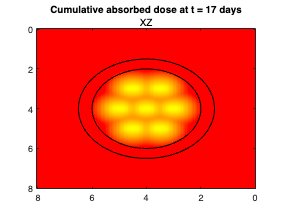

[xc2, yc2] = circle([4 4], 2,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
[xc, yc] = circle([4 4], 2.5,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
%[xc, yc,zc] = cylinder(4,100); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    

%Dose_D0 = load('Dose_D0.mat');
%Dose_cum = Dose_cum + Dose_after17d;

figure
imagesc(x_Dose,y_Dose,Dose_cum)
colormap('autumn')
hold on
[c,H] = contour(x_Dose,y_Dose,Dose_cum,[1 60 120],'ShowText','off','LineWidth',1,'LineColor','w');
plot(xc, yc, '-','linewidth',1,'Color','k');
plot(xc2 , yc2, '-','linewidth',1,'Color','k');
clabel(c,H,'FontSize',12,'Color','w','Margin',10,'LabelSpacing',80)
title('Cumulative absorbed dose at t = 17 days')
txt = {'XZ'};
subtitle(txt)
view([90 90])
%set(gca,'ZScale','log')
%zlim([10^0 10^3])
%zlim([10^0 max(max(Dose_t))])
set(gca,'ColorScale','log')

%caxis([10^0 max(max(Dose_cum))])


## 6: Intersection through centre

Dose_D0 = load('Dose_D0.mat');
Dose_D_min = load('Dose_D_min.mat');
Dose_D_max = load('Dose_D_max.mat');
%Dose_XZ_default = load('Dose_XZ_default.mat');

Dose_XZ_default = load('Dose_XZ_default.mat');
Dose_XZ_default_84d = load('Dose_XZ_default_after17d.mat');
Dose_XZ_default_84d_cum = Dose_XZ_default.Dose_cum + Dose_XZ_default_84d.Dose_after17d

Dose_YZ_default = load('Dose_YZ_default.mat');
Dose_YZ_default_84d = load('Dose_YZ_default_after17d.mat');
Dose_YZ_default_84d_cum = Dose_YZ_default.Dose_cum + Dose_YZ_default_84d.Dose_after17d

figure
plot(x_Dose,Dose_XZ_default.Dose_cum(81,:),'LineWidth',2)
hold on
plot(x_Dose,Dose_YZ_default.Dose_cum(:,81),'LineWidth',2)
yline(60,'--')
xline(2);
xline(6);
xline(1.5);
xline(6.5);
ylabel('Dose (Gy)')
xlabel('Distance (cm)')
title('Dose at t = 84 days ')
subtitle('intersection through centre')
set(gca,'YScale','log')
%ylim([10^(-3) 10^7.5])
legend('XZ','YZ')
%zlim([10^0 max(max(Dose_t(281,:)))])
%set(gca,'ColorScale','log')
%caxis([10^0 max(max(Dose_t))])

## 6: Max, min, av dose after 17 days

%Dose_D_min = load('Dose_D_min.mat');
%Dose_XZ_default = load('Dose_XZ_default.mat');

%%%%%%%%%%%%%%% Dose max %%%%%%%%%%%%%%%
time = [0 runData.timePoints/24];
figure
plot(time,Dose_D_min.maxD,'LineWidth',3)
hold on
plot(time,Dose_XZ_default.maxD,'LineWidth',3)
plot(time,Dose_D_max.maxD,'LineWidth',3)
plot(time,Dose_D0.maxD,'LineWidth',3,'Color',[0.1529    0.4000    0.1373])
yline(60,'--')
set(gca,'YScale','log')
%ylim([10^-8 10^2.5])
title('Maximum dose in PTV over time')
txt = {'for different diffusion coefficients'};
subtitle(txt)
ylabel("Dose (Gy)")
xlabel("Time (day)") 
legend("D min","D","D max",'D = 0')

%%%%%%%%%%%%%%% Dose av %%%%%%%%%%%%%%%
figure
plot(time,Dose_D_min.averageD,'LineWidth',3)
hold on
plot(time,Dose_XZ_default.averageD,'LineWidth',3,'LineStyle','--')
plot(time,Dose_D_max.averageD,'LineWidth',3)
plot(time,Dose_D0.averageD,'LineWidth',3,'Color',[0.1529    0.4000    0.1373],'LineStyle','--')
yline(60,'--')
set(gca,'YScale','log')
%ylim([10^-4 10^6])
title('Average dose in PTV over time')
txt = {'for different diffusion coefficients'};
subtitle(txt)
ylabel("Dose (Gy)")
xlabel("Time (day)") 
legend("D min","D","D max",'D = 0')

%%%%%%%%%%%%%%% Dose min %%%%%%%%%%%%%%%
figure
plot(time,Dose_D_min.minD,'LineWidth',3)
hold on
plot(time,Dose_XZ_default.minD,'LineWidth',3,'LineStyle','--')
plot(time,Dose_D_max.minD,'LineWidth',3)
plot(time,Dose_D0.minD,'LineWidth',3,'Color',[0.1529    0.4000    0.1373],'LineStyle','--')
yline(60,'--')
set(gca,'YScale','log')
%ylim([10^-6 10^2.5])
title('Minimum dose in PTV over time')
txt = {'for different diffusion coefficients'};
subtitle(txt)
ylabel("Dose (Gy)")
xlabel("Time (day)") 
legend("D min","D","D max",'D = 0')

%ylim([10^(-1) 10^9])

% % 
% % 
% % modelData.solMin = min(Dose_t);
% % modelData.solMax = max(Dose_t);
% % r = [2 , 2.5 , 3.5];  % Radius of tumour volume taken into account
% % [modelData] = dd6_2_Dose_t_average(Dose_t,r(1),r(2),r(3),centretumor(1)); % C values (max,min,average) in GTV
% % [averageC,minC,results_order] = dd6_2_Dose_t_time(Dose_t,x_Dose,y_Dose,r(1),centretumor(1)); % averageT and minT only in tumour area
% % solMax = modelData.solMax;                                                 % maxT in total area
% % t_back37 = (find(modelData.solMax<=37.2)).*0.1-0.1                        % area of all timesteps where the maximum temperature is below 37.2*C, which is the max range of normal body temperature
% % 
% % Xnodes = model.Mesh.Nodes(1,:)';
% % Ynodes = model.Mesh.Nodes(2,:)';

## 6: Plots: Intersection and distribution profile

model = dd6_dose_results_plots2D(model,modelData,Dose_t,runData);
%s6_plotPDESolution(model,T,runData) %% --> not yet fixed for 3D



# 6: Dose distribution in array to calculate Dose max min and av for GTV, PTV and PTV+ 1 cm

% % % % % 
% % % % % %load Cresults_YZ_optimize
% % % % % Cresults_YZ_default = load('Cresults_YZ_default.mat');
% % % % % x1 = Cresults_YZ_default.Xnodes;
% % % % % y1 = Cresults_YZ_default.Ynodes;
% % % % % 
% % % % % [xq,yq] = ndgrid(0:0.02:8);
% % % % % x_Dose = linspace(0,8,401);
% % % % % y_Dose = linspace(0,8,401);
% % % % % 
% % % % % [xg,yg] = meshgrid(x_Dose,y_Dose);
% % % % % x2 = reshape(xg,[],1);
% % % % % y2 = reshape(yg,[],1);
% % % % % 
% % % % % % F2 = scatteredInterpolant(x1(:),y1(:),c1(:))
% % % % % % c_voxel = F2(xq,yq)
% % % % % Dose_t = zeros(401,401,409);
% % % % % Dose_t_array = zeros(401*401,409);
% % % % % tic
% % % % % for t = 1:408
% % % % % F = scatteredInterpolant(x1(:),y1(:),Cresults_YZ_default.Cresults(:,t+1));
% % % % % conc_voxel = F(xq,yq);
% % % % % Ch = conv2(conc_voxel,Dose_kernel,'same');
% % % % % v = exp(-log(2)*(t)*3600/(16.991*24*3600)); % decay fractio: fraction of Pd-103 isotopes that have decayed over certain amount of time. Depends on time step
% % % % % Dose_t(:,:,t+1) = Dose_t(:,:,t) + Ch*v;
% % % % % Dose_t_array(:,t+1) = reshape(Dose_t(:,:,t+1),[],1);
% % % % % end
% % % % % toc
% % % % % 
% % % % % [xg,yg] = meshgrid(x_Dose,y_Dose)
% % % % % x2 = reshape(xg,[],1);
% % % % % y2 = reshape(yg,[],1);
% % % % % Dose_time = zeros(length(Dose_t_array(:,1,1)),409);
% % % % % for t = 1:409
% % % % % Dose_time(:,t) = Dose_t_array(:,t);
% % % % % end
% % % % % 
% % % % % [averageD,minD] = dd6_2_Dose_t_time(Dose_time,x2,y2,r(2),4); % averageT and minT only in tumour area
% % % % % maxD = max(Dose_time)
% % % % % 
% % % % % save Dose_YZ_default Dose_time minD maxD averageD

% % % % % 
% % % % % Cresults_XZ_default = load('Cresults_XZ_default.mat');
% % % % % x1 = Cresults_XZ_default.Xnodes;
% % % % % y1 = Cresults_XZ_default.Ynodes;
% % % % % 
% % % % % [xq,yq] = ndgrid(0:0.02:8);
% % % % % x_Dose = linspace(0,8,401);
% % % % % y_Dose = linspace(0,8,401);
% % % % % 
% % % % % Dose_t = zeros(401,401,409);
% % % % % Dose_t_array = zeros(401*401,409);
% % % % % 
% % % % % [xg,yg] = meshgrid(x_Dose,y_Dose);
% % % % % x2 = reshape(xg,[],1);
% % % % % y2 = reshape(yg,[],1);
% % % % % 
% % % % % tic
% % % % % for t = 1:408
% % % % % F = scatteredInterpolant(x1(:),y1(:),Cresults_XZ_default.Cresults(:,t+1));
% % % % % conc_voxel = F(xq,yq);
% % % % % Ch = conv2(conc_voxel,Dose_kernel,'same');
% % % % % v = exp(-log(2)*(t)*3600/(16.991*24*3600)); % decay fractio: fraction of Pd-103 isotopes that have decayed over certain amount of time. Depends on time step
% % % % % Dose_t(:,:,t+1) = Dose_t(:,:,t) + Ch*v;
% % % % % Dose_t_array(:,t+1) = reshape(Dose_t(:,:,t+1),[],1);
% % % % % end
% % % % % toc
% % % % % 
% % % % % [xg,yg] = meshgrid(x_Dose,y_Dose);
% % % % % x2 = reshape(xg,[],1);
% % % % % y2 = reshape(yg,[],1);
% % % % % Dose_time = zeros(length(Dose_t_array(:,1,1)),409);
% % % % % for t = 1:409
% % % % % Dose_time(:,t) = Dose_t_array(:,t);
% % % % % end
% % % % % 
% % % % % [averageD,minD] = dd6_2_Dose_t_time(Dose_time,x2,y2,r(2),4); % averageT and minT only in tumour area
% % % % % maxD = max(Dose_time);

%save Dose_XZ_default Dose_time minD maxD averageD

% % %Cresults_YZ_default.Cresults
% % [modelData] = dd6_2_Dose_t_average(Dose_time,x2,y2,r(1),r(2),r(3),centretumor(1)); % C values (max,min,average) in GTV

% % [xc2, yc2] = circle([4 4], 2,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
% % [xc, yc] = circle([4 4], 2.5,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
% % %[xc, yc,zc] = cylinder(4,100); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
% % 
% % Dose_XZ_default_voxel = load('Dose_XZ_default_voxel.mat');
% % 
% % figure
% % imagesc(x_Dose,y_Dose,Dose_XZ_default_voxel.Dose_XZ_default)
% % colormap('autumn')
% % hold on
% % [c,H] = contour(x_Dose,y_Dose,Dose_XZ_default_voxel.Dose_XZ_default,[30 60 90],'ShowText','off','LabelSpacing',400,'LineWidth',2,'LineColor','w');
% % plot(xc, yc, '-','linewidth',1,'Color','k');
% % plot(xc2, yc2, '-','linewidth',1,'Color','k');
% % clabel(c,H,'FontSize',15,'Color','w')
% % title('Cumulative absorbed dose at t = 17 days')
% % txt = {'XZ'};
% % subtitle(txt)
% % %set(gca,'ZScale','log')
% % %zlim([10^0 10^3])
% % %zlim([10^0 max(max(Dose_t))])
% % set(gca,'ColorScale','log')
% % caxis([10^0 max(max(Dose_t))])
% % view([90 90])

% % Dose_time(:,409)

% % Dose_YZ_optimize = load('Dose_YZ_optimize_time.mat')
% % 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%   TEST  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%Cresults_XZ_default = load('Cresults_XZ_default.mat');
Cresults_YZ_default = load('Cresults_YZ_default.mat');
Cresults_YZ_default.Cresults = Cresults_YZ_default.Cresults .*10^3;

x1 = Cresults_YZ_default.Xnodes;
y1 = Cresults_YZ_default.Ynodes;

[xq,yq] = ndgrid(0:0.05:8);

% F2 = scatteredInterpolant(x1(:),y1(:),c1(:))
% c_voxel = F2(xq,yq)

Dose_after17d = zeros(161,161);
Dose_after17d_array0 = zeros(161,161,1633);
Dose_after17d_array = zeros(161*161,1633);

F = scatteredInterpolant(x1(:),y1(:),Cresults_YZ_default.Cresults(:,409));
conc_voxel = F(xq,yq);
Ch = conv2(conc_voxel,Dose_kernel,'same');

total_time = 1632; % 17 days is one half life, resulting in 50% of the activity left. To reach activity below 5% 5 half lifes are needed -->85 days
v = zeros(1632,1);
for t = 1:1632
v(t,1) = exp(-log(2)*(t+408)*3600/(16.991*24*3600)); % decay fractio: fraction of Pd-103 isotopes that have decayed over certain amount of time. Depends on time step
Dose_after17d = Dose_after17d + Ch.*v(t,1);

Dose_after17d_array0(:,:,t+1) = Dose_after17d_array0(:,:,t) + Ch.*v(t,1);
Dose_after17d_array(:,t+1) = reshape(Dose_after17d_array0(:,:,t+1),[],1);
end
Dose_after17d_array %% 

Dose_after17d_array =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0

Dose_YZ_after17d_YZ_default_mesh = Dose_after17d;

%%%%% Save part of Dose between 17-85 days
save Dose_YZ_default_upto85days Dose_after17d Dose_after17d_array

% Dose_time is array, Dose_cum is grid
% Dose_after17d_array is array Dose_after17d is grid
Dose_array_85d = Dose_YZ_default.Dose_time + Dose_after17d_array(:,end);
Dose_grid_85d = Dose_YZ_default.Dose_cum + Dose_after17d;
save Dose_YZ_default_85d Dose_grid_85d Dose_array_85d

% Dose_XZ_default_cum_after17d = load('Dose_XZ_default_after17d.mat');
% Dose_XZ_default_cum = load('Dose_XZ_default_cum.mat');
% Dose_XZ_default_cum.Dose_XZ_default_cum = Dose_XZ_default_cum.Dose_XZ_default_cum + Dose_XZ_default_cum_after17d.Dose_after17d;

%Dose_YZ_default = load('Dose_YZ_default.mat');
%Dose_YZ_default_84d = load('Dose_YZ_default_after17d.mat');
%Dose_YZ_default_84d.Dose_after17d_array

r = [2 2.5 3.5];
centretumor = [4 4];
%Dose_YZ_84d = Dose_YZ_default.Dose_time(:,409) + Dose_YZ_default_84d.Dose_after17d_array(:,end) ;
%Dose_XZ_default_84d_reshape = reshape(Dose_XZ_default_cum_84d(:,:),[],1);
[modelData] = dd6_2_Dose_t_average(Dose_time,x2,y2,r(1),r(2),r(3),centretumor(1)); % C values (max,min,average) in GTV

% 
% Dose_XZ_cum_84d_reshape = reshape(Dose_XZ_cum_84d(:,:),[],1);
% Dose_XZ_default_mesh = Dose_XZ_default_cum.Dose_XZ_default_cum;
% 
% Dose_XZ_default_cum_mesh
% Dose_XZ_default_cum_reshape




